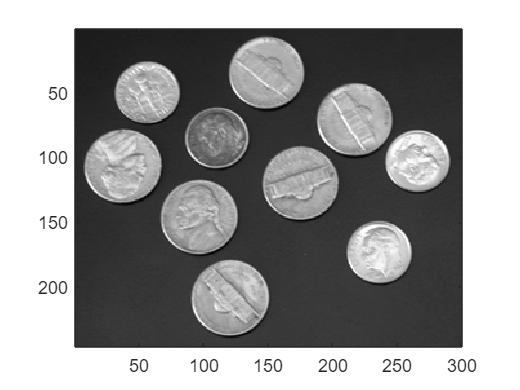

x=imread('coins.png');
imagesc(x); colormap(gray); axis image;

minimo = min(min(x));

hx=[1,0,-1;
2,0,-2;
1,0,-1];

gx= conv2(x,hx,'same')

gx =    147     0    -1     1    -1     2     3     1     1     0    -2    -3    -3     3     4     2     2    -3    -2    -3     1     8     0    -3    -2    -1     5     1    -3     1     1    -3     4     4    -4     0     3     4    -1    -3     2     1    -2     1     2    -3     0     2     2     3
   192     4     2     2     1     1     0    -1     3     0    -1    -2    -3     2     1     1     4     1    -1    -5    -2     6     2     0     0    -2     3     3     1     2     1    -5     2     3    -5     0     2     6     0    -4     4     4     1    -1    -3    -2    -1    -1     2     3
   193     5     1     0     3     1    -1     0     1     0     1     1     0    -2    -2     0     2     3     0    -4    -5     4     8     1    -1    -1     1     3     2     2    -2    -7     0     3    -1     0    -2     5     5    -4     3     7     5    -2    -4     3    -3    -5     1     1
   196     2    -3     1     5     1     1     2    -5     0     3     1     2    -4    -1  


gx(1,1) %-> porque é que dá 147?

ans = 147

x(1:4,1:4) %-> qual é a correlacao disto com em cima???

ans = 4×4 uint8 matrix
   49   50   48   49
   47   47   49   48
   48   48   49   49
   48   50   49   48


hy = rot90(hx,-1)

hy =      1     2     1
     0     0     0
    -1    -2    -1


gy = conv2(x,hy,'same')

gy =    141   190   193   195   197   198   197   195   195   196   196   195   193   193   194   194   196   199   200   199   197   196   196   197   198   197   197   199   201   203   205   205   204   204   202   200   201   204   205   203   204   207   208   207   204   201   200   200   200   201
    -4    -4     0     2     3     3     0    -3    -3    -2    -1     2     5     4    -1    -5    -6    -3     1     1    -2    -6    -6    -2     2     4     1    -1     3     6     5     3     0    -3    -3    -2    -4    -6    -4    -2    -2     0     5     7     3     2     3    -1    -4    -5
     5     7     3    -2    -3    -1     1     4     3     0     1     3     6     6     4     4     2    -1    -2     0     1     0     4     7     3     1     3     3     0    -2    -4    -7    -8    -7    -3     0    -2    -5    -3     0    -1    -1     1     2     4     9    11     9     7     5
     0    -2    -5    -3     1     1     1     2    -1    -4    -3    -3    -4    -4    -3  

gmag = sqrt(gx.^2 + gy.^2)

gmag =   203.6909  190.0000  193.0026  195.0026  197.0025  198.0101  197.0228  195.0026  195.0026  196.0000  196.0102  195.0231  193.0233  193.0233  194.0412  194.0103  196.0102  199.0226  200.0100  199.0226  197.0025  196.1632  196.0000  197.0228  198.0101  197.0025  197.0634  199.0025  201.0224  203.0025  205.0024  205.0220  204.0392  204.0392  202.0396  200.0000  201.0224  204.0392  205.0024  203.0222  204.0098  207.0024  208.0096  207.0024  204.0098  201.0224  200.0000  200.0100  200.0100  201.0224
  192.0417    5.6569    2.0000    2.8284    3.1623    3.1623         0    3.1623    4.2426    2.0000    1.4142    2.8284    5.8310    4.4721    1.4142    5.0990    7.2111    3.1623    1.4142    5.0990    2.8284    8.4853    6.3246    2.0000    2.0000    4.4721    3.1623    3.1623    3.1623    6.3246    5.0990    5.8310    2.0000    4.2426    5.8310    2.0000    4.4721    8.4853    4.0000    4.4721    4.4721    4.0000    5.0990    7.0711    4.2426    2.8284    3.1623    1.4142    4.4721  

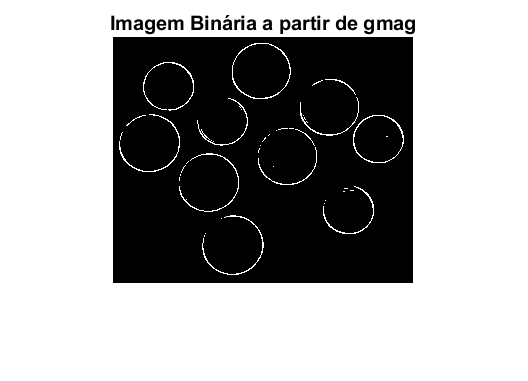

threshold = max(gmag(:)) / 2;
binaryImage = gmag > threshold;

% Mostrar a imagem binária
figure;
imshow(binaryImage);
title('Imagem Binária a partir de gmag');